## Задание 3. Синтез H_ထ-регулятора по состоянию.

Начальные условия на задание:

A = [0 1;
     0 0]

A =      0     1
     0     0


B = [0; 1]

B =      0
     1


C = [1 0;]

C =      1     0


D = [0]

D = 0


Dw = [0 1]

Dw =      0     1


Bw = [0 0 ; 
      1 0]

Bw =      0     0
     1     0


eig(A)

ans =      0
     0


**Настройка моделирования**

simTimeStart = 0;
simTimeEnd = 10;
step = 0.0001; 
time = (simTimeStart:step:simTimeEnd)';

data.time= time;
modelName = 'model_controller'; 
load_system(modelName);

% y = ampl * sin(w*t + phi)
ampl = 1;
phi = pi/2;
% f = 0.06;
f = 1.2;
w = 2*pi * f;

## **1- Первый набор Cz, Dz**

Cz = [1, 2;  
      0, 0]; 
Dz = [0;     
      1];  
% Проверка независимости
Cz'*Dz % == 0

ans =      0
     0


Bw*Dw' % == 0

ans =      0
     0


% Проверка невырожденности
Dw*Dw' % == scalar number

ans = 1

Dz'*Dz % == scalar number

ans = 1

### **1.1 - Первый выбор **γ

gamma = 100; % γ parameter, choose wisely

Q = Cz' * Cz

Q =      1     2
     2     4


R = Dz' * Dz

R = 1

% GET CONTROL
Q = Cz' * Cz;
G = (1 / gamma^2) * (Bw * Bw');

% Pre-Define smth needed for icare
E = eye(size(A)); 
S = zeros(size(B));
% Solve the Riccati equation using icare
[P, ~, EIG1] = icare(A, B, Q, R, S, E, G)

P =     0.4495    1.0001
    1.0001    2.4496


EIG1 =    -0.5176
   -1.9317



K = -inv(R) * B' * P

K =    -1.0001   -2.4496


EIG_K =  eig(A + B * K) 

EIG_K =    -0.5176
   -1.9320


mat2tex(K,2);

\begin{bmatrix}
    -1 & -2.45 \\
\end{bmatrix}


### **Рандомная частота у внешнего возмущения**

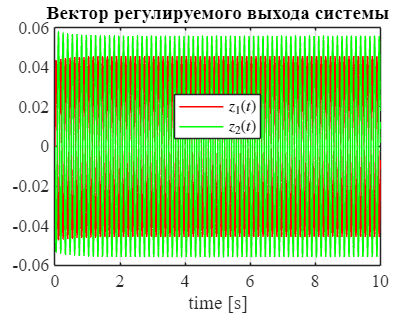

% y = ampl * sin(w*t + phi)
ampl = 1;
phi = pi/2;
f = 7.0;
w = 2*pi * f;

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x = out.x_plant.Data;
y = out.y_plant.Data;
z = out.z_plant.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z9");

### **Наихудший в каком-то смысле**

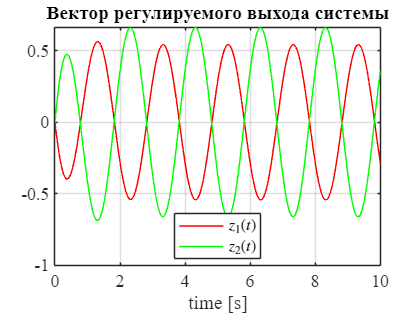

% y = ampl * sin(w*t + phi)
ampl = 1;
phi = 3*pi/2;
f = 0.5;
w = 2*pi * f;

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x = out.x_plant.Data;
y = out.y_plant.Data;
z = out.z_plant.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z10");

### **Передаточные штучки**

s = tf('s');
sys = (Cz + Dz*K)*(s*eye(2) - A - B*K)^-1 * Bw

sys =
 
  From input 1 to output...
           2 s^3 + 5.899 s^2 + 4.45 s + 1
   1:  ---------------------------------------
       s^4 + 4.899 s^3 + 8.001 s^2 + 4.9 s + 1
 
          -2.45 s^3 - 7.001 s^2 - 4.9 s - 1
   2:  ---------------------------------------
       s^4 + 4.899 s^3 + 8.001 s^2 + 4.9 s + 1
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.
Mo

disp(tf2latex(sys));

\begin{bmatrix}\frac{2s^{3} + 5.9s^{2} + 4.45s + 1}{1s^{4} + 4.9s^{3} + 8s^{2} + 4.9s + 1} & 0 \\\\ \frac{-2.45s^{3} - 7s^{2} - 4.9s - 1}{1s^{4} + 4.9s^{3} + 8s^{2} + 4.9s + 1} & 0\end{bmatrix}


tfs = {sys(1,1), sys(2,1)};
titles = {'in1→out',  'in2→out'};

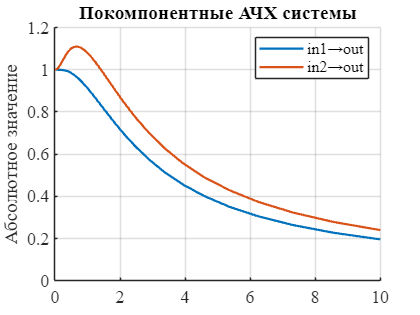

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
colors = lines(2);
hold on;
for i = 1:2
    [mag, ~, wout] = bode(tfs{i}, {0.001,10});
    plot(wout, squeeze(mag), 'Color', colors(i,:), 'LineWidth', 1.5);
end
legend(titles);
grid on;
ylabel('Абсолютное значение');
title("Покомпонентные АЧХ системы")
save_file("freq_ampl_components5");

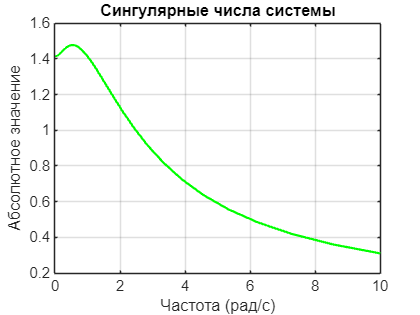

[sv, wout] = sigma(sys(:,1), {0.01,10});  
sv = squeeze(sv);        
figure;
plot(wout, sv, 'g', 'LineWidth', 1.5);  
title('Сингулярные числа системы');
xlabel('Частота (рад/с)');
ylabel('Абсолютное значение');
grid on;
save_file("singular_values5");

% Вычисление H_2 и H_inf норм
H2_norm = norm(sys, 2) % H2_norm = sqrt(trace(Bw'*P*Bw))

H2_norm = 1.5651

hinf_norm = norm(sys, inf)

hinf_norm = 1.4776

### **1.2 - Второй выбор **γ

gamma = 1.5; % γ parameter, choose wisely

Q = Cz' * Cz

Q =      1     2
     2     4


R = Dz' * Dz

R = 1

% GET CONTROL
Q = Cz' * Cz;
G = (1 / gamma^2) * (Bw * Bw');

% Pre-Define smth needed for icare
E = eye(size(A)); 
S = zeros(size(B));
% Solve the Riccati equation using icare
[P, ~, EIG1] = icare(A, B, Q, R, S, E, G)

P =     0.5852    1.3416
    1.3416    3.4684


EIG1 =    -0.5358
   -1.3911



K = -inv(R) * B' * P

K =    -1.3416   -3.4684


EIG_K =  eig(A + B * K) 

EIG_K =    -0.4435
   -3.0249


mat2tex(K,2);

\begin{bmatrix}
    -1.34 & -3.47 \\
\end{bmatrix}


### **Рандомная частота у внешнего возмущения**

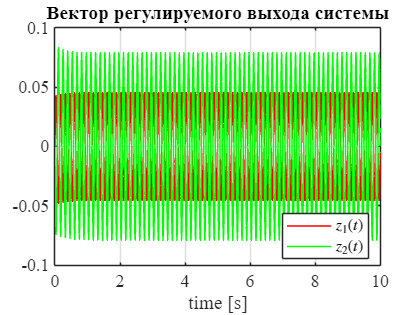

% y = ampl * sin(w*t + phi)
ampl = 1;
phi = pi/2;
f = 7.0;
w = 2*pi * f;

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x = out.x_plant.Data;
y = out.y_plant.Data;
z = out.z_plant.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z11");

### **Наихудший в каком-то смысле**

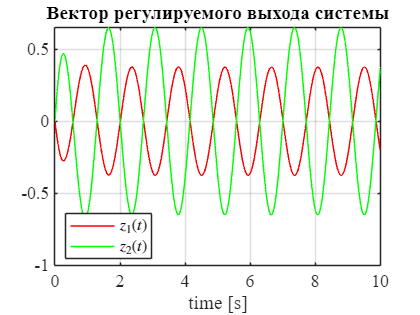

% y = ampl * sin(w*t + phi)
ampl = 1;
phi = 3*pi/2;
f = 0.7;
w = 2*pi * f;

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x = out.x_plant.Data;
y = out.y_plant.Data;
z = out.z_plant.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z12");

### **Передаточные штучки**

s = tf('s');
sys = (Cz + Dz*K)*(s*eye(2) - A - B*K)^-1 * Bw

sys =
 
  From input 1 to output...
           2 s^3 + 7.937 s^2 + 6.152 s + 1.342
   1:  -------------------------------------------
       s^4 + 6.937 s^3 + 14.71 s^2 + 9.307 s + 1.8
 
         -3.468 s^3 - 13.37 s^2 - 9.307 s - 1.8
   2:  -------------------------------------------
       s^4 + 6.937 s^3 + 14.71 s^2 + 9.307 s + 1.8
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.


disp(tf2latex(sys));

\begin{bmatrix}\frac{2s^{3} + 7.94s^{2} + 6.15s + 1.34}{1s^{4} + 6.94s^{3} + 14.71s^{2} + 9.31s + 1.8} & 0 \\\\ \frac{-3.47s^{3} - 13.37s^{2} - 9.31s - 1.8}{1s^{4} + 6.94s^{3} + 14.71s^{2} + 9.31s + 1.8} & 0\end{bmatrix}


tfs = {sys(1,1), sys(2,1)};
titles = {'in1→out',  'in2→out'};

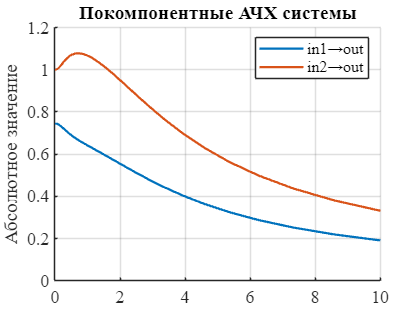

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
colors = lines(2);
hold on;
for i = 1:2
    [mag, ~, wout] = bode(tfs{i}, {0.001,10});
    plot(wout, squeeze(mag), 'Color', colors(i,:), 'LineWidth', 1.5);
end
legend(titles);
grid on;
ylabel('Абсолютное значение');
title("Покомпонентные АЧХ системы")
save_file("freq_ampl_components6");

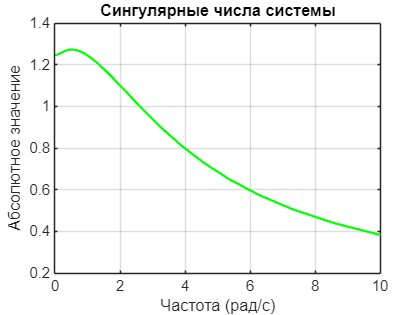

[sv, wout] = sigma(sys(:,1), {0.01,10});  
sv = squeeze(sv);        
figure;
plot(wout, sv, 'g', 'LineWidth', 1.5);  
title('Сингулярные числа системы');
xlabel('Частота (рад/с)');
ylabel('Абсолютное значение');
grid on;
save_file("singular_values6");

% Вычисление H_2 и H_inf норм
H2_norm = norm(sys, 2) % H2_norm = sqrt(trace(Bw'*P*Bw))

H2_norm = 1.6161

hinf_norm = norm(sys, inf)

hinf_norm = 1.2733

## **2- Второй набор Cz, Dz**

Cz = [3, 1;  
      0, 0]; 
Dz = [0;     
      2]; 
% Проверка независимости
Cz'*Dz % == 0

ans =      0
     0


Bw*Dw' % == 0

ans =      0
     0


% Проверка невырожденности
Dw*Dw' % == scalar number

ans = 1

Dz'*Dz % == scalar number

ans = 4

### **2.1 - Первый выбор **γ

gamma = 10; % γ parameter, choose wisely

Q = Cz' * Cz

Q =      9     3
     3     1


R = Dz' * Dz

R = 4

% GET CONTROL
Q = Cz' * Cz;
G = (1 / gamma^2) * (Bw * Bw');

% Pre-Define smth needed for icare
E = eye(size(A)); 
S = zeros(size(B));
% Solve the Riccati equation using icare
[P, ~, EIG1] = icare(A, B, Q, R, S, E, G)

P =     7.9191    6.1237
    6.1237    7.4295


EIG1 =   -0.8915 + 0.8215i
  -0.8915 - 0.8215i



K = -inv(R) * B' * P

K =    -1.5309   -1.8574


EIG_K =  eig(A + B * K) 

EIG_K =   -0.9287 + 0.8176i
  -0.9287 - 0.8176i


mat2tex(K,2);

\begin{bmatrix}
    -1.53 & -1.86 \\
\end{bmatrix}


### **Рандомная частота у внешнего возмущения**

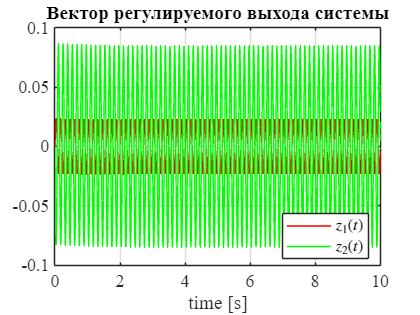

% y = ampl * sin(w*t + phi)
ampl = 1;
phi = pi/2;
f = 7.0;
w = 2*pi * f;

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x = out.x_plant.Data;
y = out.y_plant.Data;
z = out.z_plant.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z13");

### **Наихудший в каком-то смысле**

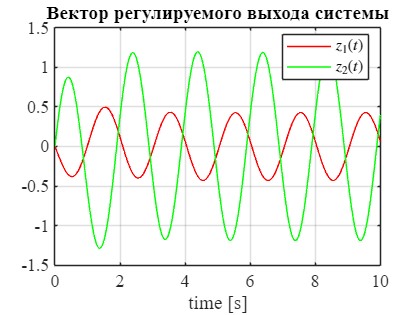

% y = ampl * sin(w*t + phi)
ampl = 1;
phi = 3*pi/2;
f = 0.5;
w = 2*pi * f;

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x = out.x_plant.Data;
y = out.y_plant.Data;
z = out.z_plant.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z14");

### **Передаточные штучки**

s = tf('s');
sys = (Cz + Dz*K)*(s*eye(2) - A - B*K)^-1 * Bw

sys =
 
  From input 1 to output...
             s^3 + 4.857 s^2 + 7.103 s + 4.593
   1:  ---------------------------------------------
       s^4 + 3.715 s^3 + 6.512 s^2 + 5.687 s + 2.344
 
         -3.715 s^3 - 9.962 s^2 - 11.37 s - 4.688
   2:  ---------------------------------------------
       s^4 + 3.715 s^3 + 6.512 s^2 + 5.687 s + 2.344
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.


disp(tf2latex(sys));

\begin{bmatrix}\frac{1s^{3} + 4.86s^{2} + 7.1s + 4.59}{1s^{4} + 3.71s^{3} + 6.51s^{2} + 5.69s + 2.34} & 0 \\\\ \frac{-3.71s^{3} - 9.96s^{2} - 11.37s - 4.69}{1s^{4} + 3.71s^{3} + 6.51s^{2} + 5.69s + 2.34} & 0\end{bmatrix}


tfs = {sys(1,1), sys(2,1)};
titles = {'in1→out',  'in2→out'};

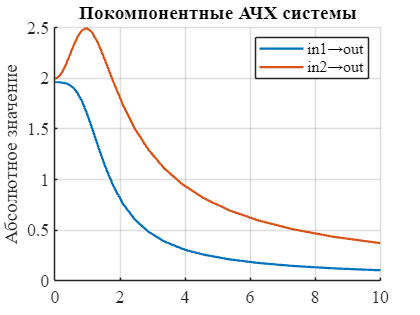

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
colors = lines(2);
hold on;
for i = 1:2
    [mag, ~, wout] = bode(tfs{i}, {0.001,10});
    plot(wout, squeeze(mag), 'Color', colors(i,:), 'LineWidth', 1.5);
end
legend(titles);
grid on;
ylabel('Абсолютное значение');
title("Покомпонентные АЧХ системы")
save_file("freq_ampl_components7");

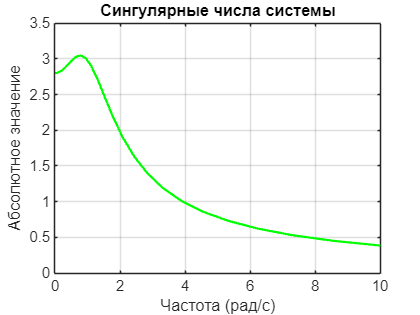

[sv, wout] = sigma(sys(:,1), {0.01,10});  
sv = squeeze(sv);        
figure;
plot(wout, sv, 'g', 'LineWidth', 1.5);  
title('Сингулярные числа системы');
xlabel('Частота (рад/с)');
ylabel('Абсолютное значение');
grid on;
save_file("singular_values7");

% Вычисление H_2 и H_inf норм
H2_norm = norm(sys, 2) % H2_norm = sqrt(trace(Bw'*P*Bw))

H2_norm = 2.6861

hinf_norm = norm(sys, inf)

hinf_norm = 3.0465

### **2.2 - Второй выбор **γ

gamma = 2.5; % γ parameter, choose wisely

Q = Cz' * Cz

Q =      9     3
     3     1


R = Dz' * Dz

R = 4

% GET CONTROL
Q = Cz' * Cz;
G = (1 / gamma^2) * (Bw * Bw');

% Pre-Define smth needed for icare
E = eye(size(A)); 
S = zeros(size(B));
% Solve the Riccati equation using icare
[P, ~, EIG1] = icare(A, B, Q, R, S, E, G)

P =    10.7477   10.0000
   10.0000   15.2753


EIG1 =   -0.6874 + 0.6538i
  -0.6874 - 0.6538i



K = -inv(R) * B' * P

K =    -2.5000   -3.8188


EIG_K =  eig(A + B * K) 

EIG_K =    -0.8390
   -2.9798


mat2tex(K,2);

\begin{bmatrix}
    -2.5 & -3.82 \\
\end{bmatrix}


### **Рандомная частота у внешнего возмущения**

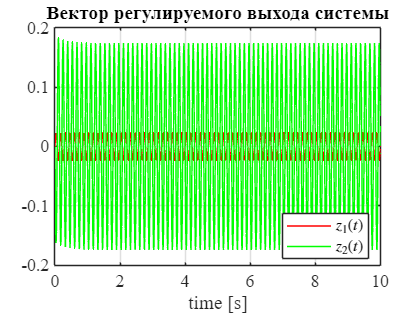

% y = ampl * sin(w*t + phi)
ampl = 1;
phi = pi/2;
f = 7.0;
w = 2*pi * f;

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x = out.x_plant.Data;
y = out.y_plant.Data;
z = out.z_plant.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z15");

### **Наихудший в каком-то смысле**

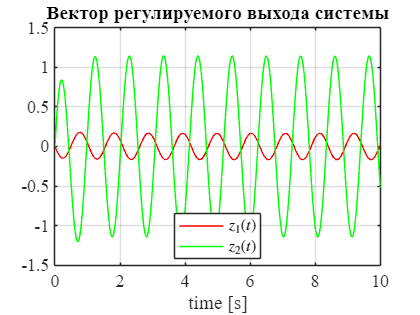

% y = ampl * sin(w*t + phi)
ampl = 1;
phi = 3*pi/2;
f = 0.95;
w = 2*pi * f;

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x = out.x_plant.Data;
y = out.y_plant.Data;
z = out.z_plant.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z16");

### **Передаточные штучки**

s = tf('s');
sys = (Cz + Dz*K)*(s*eye(2) - A - B*K)^-1 * Bw

sys =
 
  From input 1 to output...
             s^3 + 6.819 s^2 + 13.96 s + 7.5
   1:  --------------------------------------------
       s^4 + 7.638 s^3 + 19.58 s^2 + 19.09 s + 6.25
 
         -7.638 s^3 - 34.17 s^2 - 38.19 s - 12.5
   2:  --------------------------------------------
       s^4 + 7.638 s^3 + 19.58 s^2 + 19.09 s + 6.25
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.


disp(tf2latex(sys));

\begin{bmatrix}\frac{1s^{3} + 6.82s^{2} + 13.96s + 7.5}{1s^{4} + 7.64s^{3} + 19.58s^{2} + 19.09s + 6.25} & 0 \\\\ \frac{-7.64s^{3} - 34.17s^{2} - 38.19s - 12.5}{1s^{4} + 7.64s^{3} + 19.58s^{2} + 19.09s + 6.25} & 0\end{bmatrix}


tfs = {sys(1,1), sys(2,1)};
titles = {'in1→out',  'in2→out'};

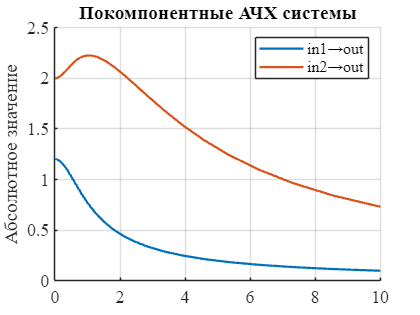

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
colors = lines(2);
hold on;
for i = 1:2
    [mag, ~, wout] = bode(tfs{i}, {0.001,10});
    plot(wout, squeeze(mag), 'Color', colors(i,:), 'LineWidth', 1.5);
end
legend(titles);
grid on;
ylabel('Абсолютное значение');
title("Покомпонентные АЧХ системы")
save_file("freq_ampl_components8");

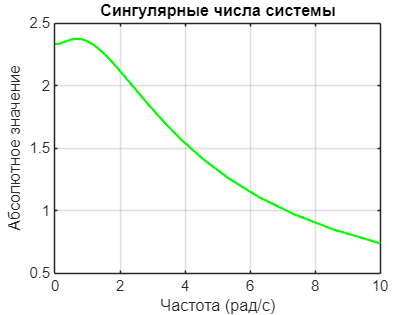

[sv, wout] = sigma(sys(:,1), {0.01,10});  
sv = squeeze(sv);        
figure;
plot(wout, sv, 'g', 'LineWidth', 1.5);  
title('Сингулярные числа системы');
xlabel('Частота (рад/с)');
ylabel('Абсолютное значение');
grid on;
save_file("singular_values8");

% Вычисление H_2 и H_inf норм
H2_norm = norm(sys, 2) % H2_norm = sqrt(trace(Bw'*P*Bw))

H2_norm = 3.0902

hinf_norm = norm(sys, inf)

hinf_norm = 2.3746

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab11\latex11\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end